# **MATLAB TUTORIAL 6:**

# **ARRAY OPERATORS**

Please complete the following problems in this Livescript unless otherwise indicated. Remember to create a folder with the name Tutorial6_username (e.g. if your username is abc, then Tutorial6_abc) to put all the files and figures related to the Tutorial (including this Livescript). When you are finished, zip the folder and upload it to the BlackBoard Assignment submission box. 

### 6.1 Matrix Algebra

**Matrix multiplication and elementwise array multiplication**

Two arrays A and B representing matrices A and B are given as:

$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack$    and  $B=\left\lbrack \begin{array}{ccc}
0\ldotp 4667 & -0\ldotp 3333 & 0\ldotp 1333\\
-0\ldotp 0333 & 0\ldotp 6667 & 0\ldotp 3667\\
-0\ldotp 3333 & -0\ldotp 3333 & 0\ldotp 3333
\end{array}\right\rbrack$

Multiply the matrices C = AB =

% Define A and B
A=[1, 2, 3; 4, 5, 6; 7, 8, 9];
B=[0.4667, -0.3333, 0.1333; -0.0333, 0.6667, 0.3667; -0.3333, -0.3333, 0.3333];

% Multiply A and B
C=A*B

C =    -0.5998    0.0002    1.8666
   -0.2995    0.0005    4.3665
    0.0008    0.0008    6.8664


How are the matrices A and B related?

**They are not meaningfully related! It was an attempt to get you to try the diﬀerent matrix operations we have seen.**

Multiply the arrays A and B elementwise, using the .* operator: D = A.*B =

D=A.*B

D =     0.4667   -0.6666    0.3999
   -0.1332    3.3335    2.2002
   -2.3331   -2.6664    2.9997


Invert matrix D: $D^{-1}$ =

Dinv=inv(D)

Dinv =     1.1487    0.0676   -0.2027
   -0.3427    0.1689   -0.0782
    0.5888    0.2027    0.1062


**Singular Matrices**

A matrix G is given as:


$$G=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
-\frac{1}{3} & -\frac{2}{3} & -1\\
7 & 8 & 9
\end{array}\right\rbrack$$


What happens if you try to invert matrix G?

% Define G
G=[1,2,3;-1/3,-2/3,-1;7,8,9]; 
inv(G)

ans = 	1.0e+16 *

    0.7881    2.3644    0.0000
   -1.5763   -4.7288   -0.0000
    0.7881    2.3644   -0.0000


"Warning: Matrix is close to singular or badly scaled. Results may be inaccurate. RCOND =  8.133502e-19."

Compute the determinant of matrix G

d=det(G)

d = 2.5377e-16

### 6.2 Linear Equations

Use Matlab to solve the following system of equations:


$$3x_1+1x_2+6x_3=12 \\
5x_1+4x_2+2x_3=1 \\
1x_1+3x_2+8x_3=-3

$$


% Define arrays
A=[3,1,6;5,4,2;1,3,8]; 
B=[12;1;-3]; 

x=A\B 

x =     3.6604
   -4.8113
    0.9717


%or x=inv(A)*B


### 6.3 Array Operations and Sub-arrays

**Plotting curves**

Create an array x of values from -10 to 10, spaced by 0.1 (use the colon operator). Use an array-operation to compute the array y y = sin(1/x). Plot array y versus array x.

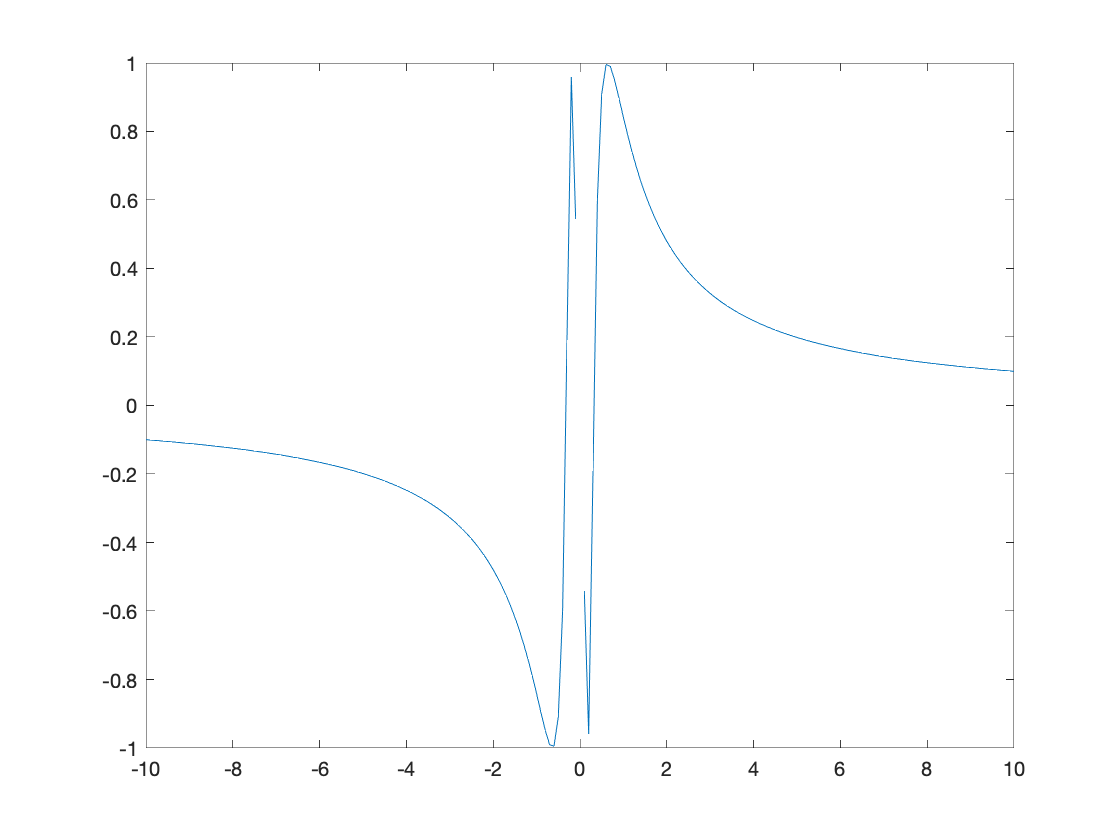

x=-10:0.1:10; 
y=sin(1./x); 
%use ./ as elementwise operations must be used 
%This produces the equivalent to a loop y(i)=sin(1/x(i)) 
%for x=0, 1/x becomes Inf giving a value of NaN for y(0)

plot(x,y) %the NaN is skipped by the plot() function

**Plotting vectors and streamlines**

Create a vector plot (using the function  **quiver() **) of the velocity ﬁeld  *u = y + sin(x)*,  *v = cos(x + y)* in the range 0 < x < 10 and 0 < y < 5. Plot the same velocity ﬁeld with streamlines using the function **streamslice()**

 Try this program ﬁrst using loops.

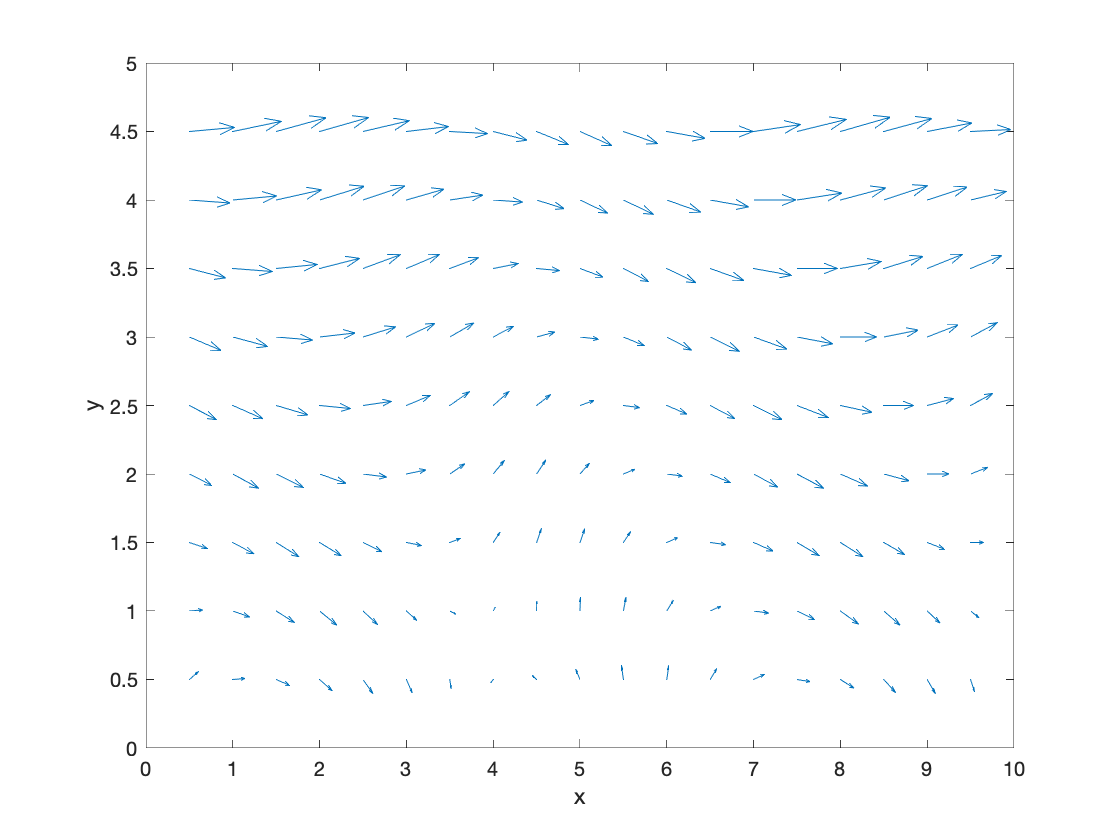

clear 
clc
step=0.5; 
x=step:step:10-step; %remember that 0<x<10 
y=step:step:5-step;  %remember that 0<y<5

%Create array of velocity field (u,v) 
%Loop over x and y vectors to calculate u and v at each (x,y) co-ordinate 
for i=1:length(x) 
    for j=1:length(y) 
        %calculate velocities 
        u(i,j)=y(j)+sin(x(i)); 
        v(i,j)=cos(x(i)+y(j)); 
        %Optional: save associated array of (x,y) coordinates produced by the loop 
        %to compare to meshgrid() output 
        xgrid(i,j)=x(i);
        ygrid(i,j)=y(j); 
    end
end

%open figure and plot vectors figure; 
%u and v arrays need to be transposed to match orientation of x,y. 
% 
%Compare xgrid and ygrid to meshgrid() output yourself to see the difference. 
quiver(x,y,u',v'); 
xlabel('x'); 
ylabel('y');


%new figure for streamline plot
figure; 
streamslice(x,y,u',v'); 
xlabel('x'); 
ylabel('y');

Modify your program to only use array operations. The **meshgrid()** function may prove essential.

clear
clc
step=0.5;
x=step:step:10-step; %remember that 0<x<10 
y=step:step:5-step; %remember that 0<y<5

%call meshgrid to create 2D arrays for x,y mesh
% %meshgrid arrays x1,y1 are arranged in cartesian x,y directions,
% %not in array index directions. 
[x1,y1]=meshgrid(x,y); 

%calculate velocities 
u=y1+sin(x1);
v=cos(x1+y1);

%open new figure & plot vector graph 
figure(1) 
quiver(x1,y1,u,v) 
xlabel('x') 
ylabel('y')
%new figure for streamline plot 
figure(2) 
streamslice(x1,y1,u,v)
xlabel('x') 
ylabel('y')

What do the arrays produced by **meshgrid()** look like? Are they arranged in the order you would expect?

**They are 2D matrices of size (length(lentgh(y),length(x)).**

**Extracting sub-matrices**

A matrix M is given as: 


$$M=\left\lbrack \begin{array}{cccccc}
1 & 2 & 3 & 5 & 8\ldotp 5 & 2\\
-\frac{1}{3} & -\frac{2}{3} & -1 & 3 & 2 & -5\ldotp 1\\
7 & 8 & 9 & 2\ldotp 01 & -1 & 3
\end{array}\right\rbrack$$


 Copy the right half of matrix M (i.e. columns 4, 5 and 6) to matrix N.

% Define M
M=[1 2 3 5 8.5 2 ;-1/3 -0.6666 -1.0 3 2 -5.1;7 8 9 2.01 -1 3];
 
N=M(:,4:6)

N =     5.0000    8.5000    2.0000
    3.0000    2.0000   -5.1000
    2.0100   -1.0000    3.0000


 Copy the odd numbered columns (1,3,5,...) of the 2nd row of matrix M to a matrix K.

K=M(2,1:2:end)

K =    -0.3333   -1.0000    2.0000


**Area of a Circle**

We certainly know the value of π to very high precision. We now try a Monte-Carlo method, i.e. a method based on random numbers, to compute its value.

The area of a circle of radius r = 1 is π. To compute the area, we can create N random points, where every point N has a random x coordinate and a random y coordinate. We only consider random points where all the coordinates are in the range of [-1, 1], i.e. inside a square.

The ratio of the area of the circle to that of the square can therefore be approximated by the number of points inside the circle divided by the total number of points, as the number of points nears inﬁnity. Store the coordinates of the random points in a N×2 matrix. A point is located inside the circle if$x^2+y^2<1$ . To compute π, it is suﬃcient to multiply the area of the square (4) with the number Ni of points inside the circle divided by the overall number N of points. To improve the precision, you can simply increase the number of points.

Hint: A problem such as this where a particular operation is repeated for diﬀerent inputs lends itself very well to the use of a function.

Write the program.

%script to compute the value of pi using a Monte-Carlo method 
%calls the function MCgetpi(N)
%written by E. Levis, 7/1,13

%housekeeping 
clear;clc

for i=1:7 
    N=10^(i-1); 
    MCpi=MCgetpi(N); 
    disp(['For ',num2str(N),' points, pi =',num2str(MCpi)]); 
end

For 1 points, pi =0
For 10 points, pi =2.4
For 100 points, pi =3.24
For 1000 points, pi =3.244
For 10000 points, pi =3.1228
For 100000 points, pi =3.1397
For 1000000 points, pi =3.1421


%end of script


Your value for π(N = 1):

Your value for π(N = 10):

Your value for π(N = 100):

Your value for π(N = 1,000):

Your value for π(N = 10,000):

Your value for π(N = 100,000):

Your value for π(N = 1,000,000):

Once your script is working, try to eliminate all loops and if statements by using array operations. Keep in mind that relational operators (==, >, < etc.) can be used with arrays. For instance:

>> a=([1,2,6,3,2,7,10,9] > 3)

will return an array a equal to [0,0,1,0,0,1,1,1].

%script to compute the value of pi using a Monte-Carlo method 
%calls the function MCgetpiA(N)
%written by E. Levis, 7/1,13

%housekeeping 
clear;clc

for i=1:7 
    N=10^(i-1); 
    MCpi=MCgetpiA(N); 
    disp(['For ',num2str(N),' points, pi =',num2str(MCpi)]); 
end

For 1 points, pi =4
For 10 points, pi =4
For 100 points, pi =3.04
For 1000 points, pi =3.148
For 10000 points, pi =3.1252
For 100000 points, pi =3.146
For 1000000 points, pi =3.1416


%end of script


**Finding Primes and Plotting them**

Write a program that ﬁnds all the primes in the interval from lower bound to upper bound, and then plots their distribution.

The program should ﬁrst prompt the user for a range of integers, asking for a lower and upper bound. A for-loop will then iterate over each number, calling the function written previously to check whether the number is a prime. Then the function will mark integers that are primes with a value of 1, other integers with 0.

Finally, the script must plot the resulting array to visualise the distribution of the primes.

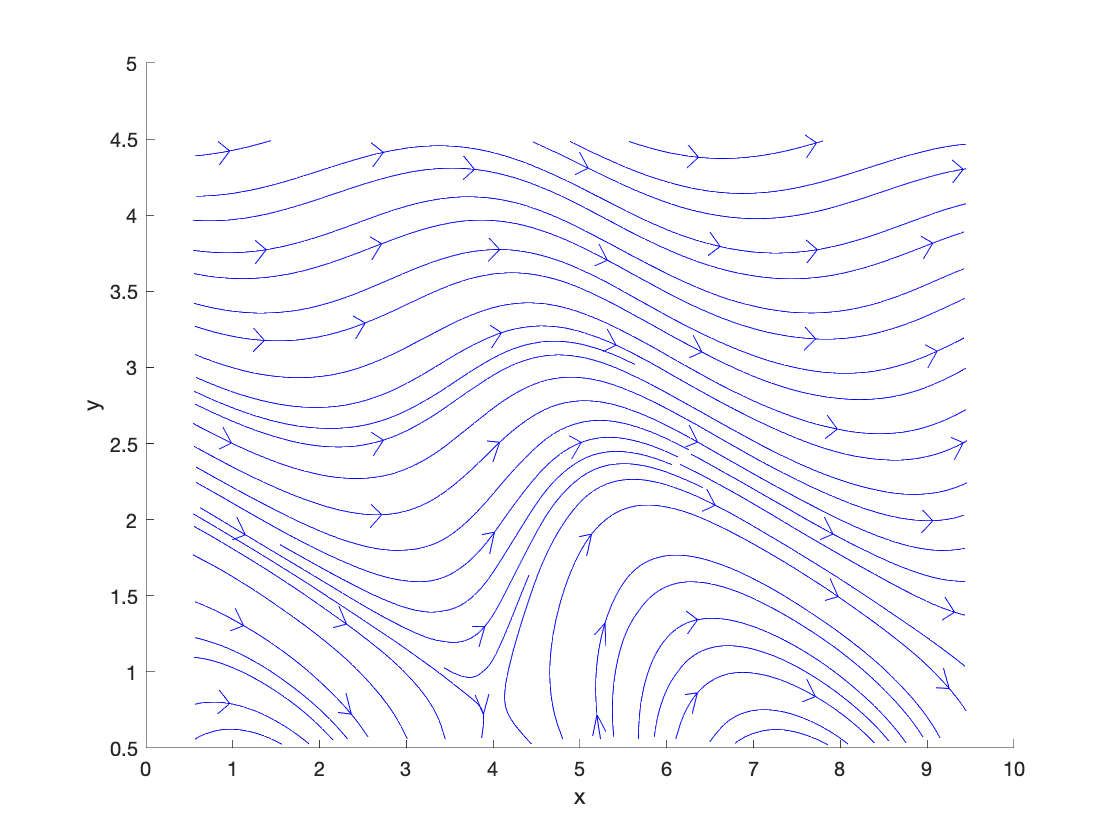

%script that plots whether numbers in a user defined range 
%are is prime or not. 
%Used the function myprm() written in the past tutorial
%written by E. Levis, 7/1/13

%housekeeping 
clear;clc;

%user input 
lower=input('Input a lower bound integer greater than 1: '); 

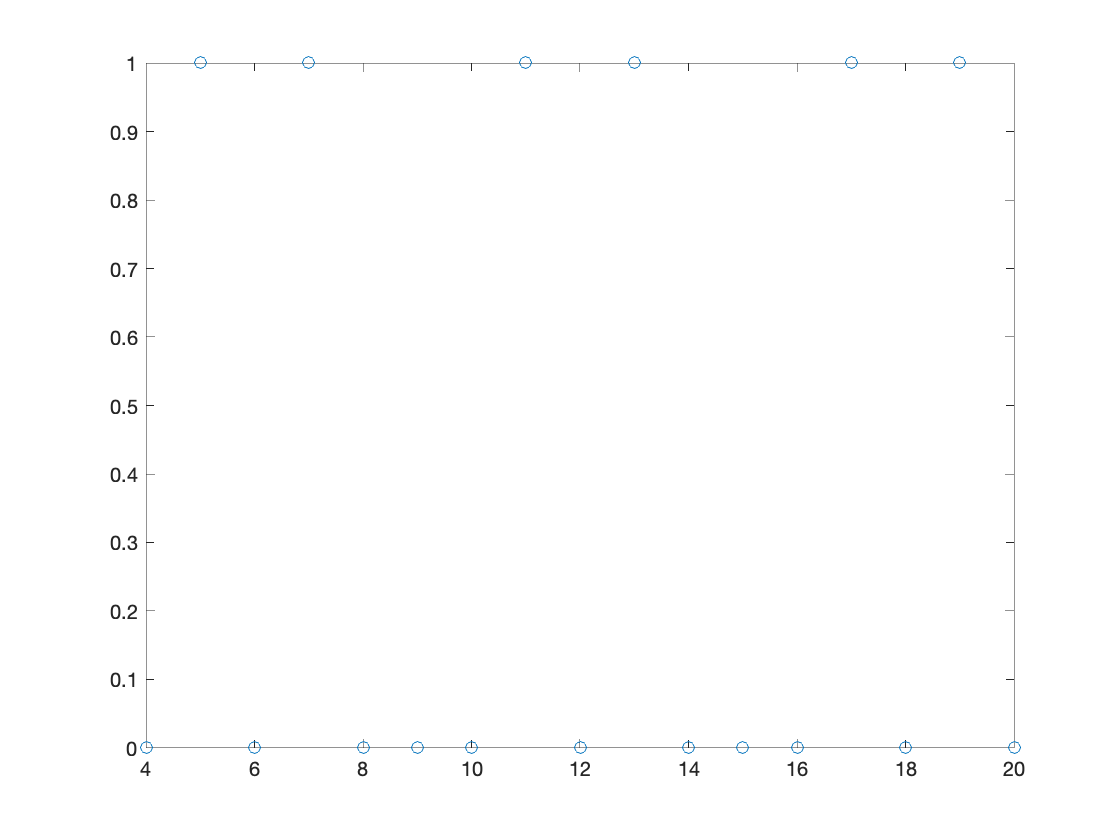

upper=input('Input an upper bound integer lower than 10000: '); 

%initialise the results array 
res=zeros(upper-lower+1,1);
%check each value to check 
for i=lower:upper 
    res(i-lower+1)=checkPrime(i);
    %plot in real time 
    plot(lower:i,res(1:i-lower+1),'o'); 
    drawnow %make sure the plot is refreshed end %end of script
end